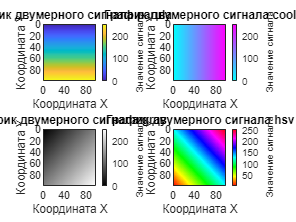

%1 задание
% Формирование четырёх двумерных сигналов и их отображение
% в разных цветовых палитрах (parula, cool, gray, hsv)

dx = 1; X = 99;              % шаг и правая граница по X
dy = 1; Y = 99;              % шаг и правая граница по Y

x = 0 : dx : X;              % координатная сетка по X
y = 0 : dy : Y;              % координатная сетка по Y

[Xg, Yg] = meshgrid(x, y);   % двумерные сетки координат

s1 = Yg * 2.55;              % сигнал, линейно зависящий от Y
s2 = Xg * 2.55;              % сигнал, линейно зависящий от X
s3 = (Xg + Yg) * 2.55/2;     % диагональный градиент
s4 = (100 + Xg - Yg) * 2.55/2; % обратный диагональный градиент

fig_im = figure();           % окно для четырёх графиков

ax1 = subplot(2,2,1);       
imagesc(x,y,s1);             
colormap(ax1, "parula");     % палитра parula
title('График двумерного сигнала parula');
xlabel('Координата X')
ylabel('Координата Y')
cb = colorbar;               
cb.Label.String = 'Значение сигнала';

ax2 = subplot(2,2,2);        
imagesc(x,y,s2);             
colormap(ax2, "cool");       % палитра cool
title('График двумерного сигнала cool');
xlabel('Координата X')
ylabel('Координата Y')
cb = colorbar;
cb.Label.String = 'Значение сигнала';

ax3 = subplot(2,2,3);        
imagesc(x,y,s3);             
colormap(ax3, "gray");       % палитра gray
title('График двумерного сигнала gray');
xlabel('Координата X')
ylabel('Координата Y')
cb = colorbar;
cb.Label.String = 'Значение сигнала';

ax4 = subplot(2,2,4);        
imagesc(x,y,s4);             
colormap(ax4, "hsv");        % палитра hsv
title('График двумерного сигнала hsv');
xlabel('Координата X')
ylabel('Координата Y')
cb = colorbar;
cb.Label.String = 'Значение сигнала';

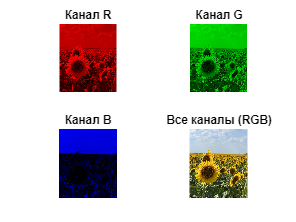

%2 задание
% Выделение каналов R, G, B из цветного изображения
% и их отображение каждый в своей цветовой палитре

img = imread('img.jpg');   % чтение изображения
R = img(:,:,1);              % красный канал
G = img(:,:,2);              % зелёный канал
B = img(:,:,3);              % синий канал

N = 256;                     % число уровней палитры
redMap   = [linspace(0,1,N)', zeros(N,2)];              % чёрный → красный
greenMap = [zeros(N,1), linspace(0,1,N)', zeros(N,1)];  % чёрный → зелёный
blueMap  = [zeros(N,2), linspace(0,1,N)'];              % чёрный → синий

figure('Color','w');         % окно для 4 изображений

ax1 = subplot(2,2,1);
imagesc(ax1, R);             % показываем R-канал
axis(ax1,'image','off');     % пропорции + без осей
colormap(ax1, redMap);       % красная палитра
title(ax1,'Канал R');

ax2 = subplot(2,2,2);
imagesc(ax2, G);             % G-канал
axis(ax2,'image','off');
colormap(ax2, greenMap);     % зелёная палитра
title(ax2,'Канал G');

ax3 = subplot(2,2,3);
imagesc(ax3, B);             % B-канал
axis(ax3,'image','off');
colormap(ax3, blueMap);      % синяя палитра
title(ax3,'Канал B');

ax4 = subplot(2,2,4);
image(ax4, img);             % исходное RGB-изображение
axis(ax4,'image','off');
title(ax4,'Все каналы (RGB)');

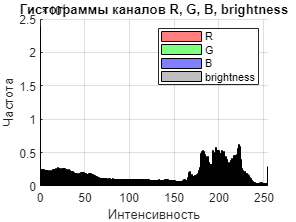


%3 задание
% Построение гистограмм по каналам R, G, B и яркости (brightness)

W = rgb2gray(img);           

% Границы и центры бинов (256 бинов -> интенсивности 0…255)
edges   = 0:1:256;
centers = edges(1:end-1) + 0.5;

% Частоты по каждому каналу
countsR = histcounts(R(:), edges);
countsG = histcounts(G(:), edges);
countsB = histcounts(B(:), edges);
countsW = histcounts(W(:), edges);

figure('Color','w');
hold on;                     


bar(centers, countsR, 1, 'FaceColor','r', 'EdgeColor','k', 'LineWidth', 0.5, 'FaceAlpha', 0.5);
bar(centers, countsG, 1, 'FaceColor','g', 'EdgeColor','k', 'LineWidth', 0.5, 'FaceAlpha', 0.5);
bar(centers, countsB, 1, 'FaceColor','b', 'EdgeColor','k', 'LineWidth', 0.5, 'FaceAlpha', 0.5);
bar(centers, countsW, 1, 'FaceColor',[0.5 0.5 0.5], 'EdgeColor','k', 'LineWidth', 0.5, 'FaceAlpha', 0.5);

hold off;
xlim([0 255]);               % ось X ровно по интенсивностям 0…255
xlabel('Интенсивность');
ylabel('Частота');
title('Гистограммы каналов R, G, B, brightness');
legend('R','G','B','brightness');
grid on;

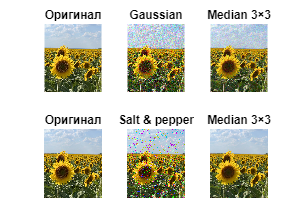


%4 задание
% Добавление шума (gaussian и salt & pepper) и медианная фильтрация
% собственной функцией myMedianFilter

img = imread('img.jpg');   % uint8

% Гауссов шум: среднее 0, дисперсия 0.01
imgGauss = imnoise(img, 'gaussian', 0, 0.01);

% Salt & pepper: 5% испорченных пикселей
imgSP = imnoise(img, 'salt & pepper', 0.05);

k = 3;                                     % размер окна медианного фильтра
imgGaussFilt = myMedianFilter(imgGauss, k);% фильтрация гауссова шума
imgSPFilt    = myMedianFilter(imgSP,    k);% фильтрация salt & pepper

figure('Color','w');

subplot(2,3,1); imshow(img);          title('Оригинал');
subplot(2,3,2); imshow(imgGauss);     title('Gaussian');
subplot(2,3,3); imshow(imgGaussFilt); title('Median 3×3');

subplot(2,3,4); imshow(img);          title('Оригинал');
subplot(2,3,5); imshow(imgSP);        title('Salt & pepper');
subplot(2,3,6); imshow(imgSPFilt);    title('Median 3×3');


%5 задание
% Перебор размеров окна медианного фильтра,
% расчёт MSE относительно оригинала и построение графика MSE(k)

img = imread('img.jpg');

% Зашумлённые версии
imgGauss = imnoise(img, 'gaussian', 0, 0.01);
imgSP    = imnoise(img, 'salt & pepper', 0.05);

ks = [3 5 7 9 11 13];              % набор размеров окна

mseGauss = zeros(size(ks));  % массив MSE для гауссова шума
mseSP    = zeros(size(ks));  % массив MSE для salt & pepper
resGauss = cell(size(ks));   % отфильтрованные изображения (гаусс)
resSP    = cell(size(ks));   % отфильтрованные изображения (S&P)

for i = 1:numel(ks)          % прогон по всем окнам
    k = ks(i);

    resGauss{i} = myMedianFilter(imgGauss, k);   % фильтрация
    resSP{i}    = myMedianFilter(imgSP,    k);

    mseGauss(i) = calcMSE(img, resGauss{i});     % MSE к оригиналу
    mseSP(i)    = calcMSE(img, resSP{i});
end

% Таблица MSE в консоль
fprintf('Окно | MSE Gaussian | MSE S&P\n');

Окно | MSE Gaussian | MSE S&P


for i = 1:numel(ks)
    fprintf('%2dx%-2d | %12.4f | %12.4f\n', ks(i), ks(i), mseGauss(i), mseSP(i));
end

 3x3  |     224.9215 |     110.2741
 5x5  |     288.3448 |     239.7802
 7x7  |     375.0457 |     351.7405
 9x9  |     460.2237 |     449.6907
11x11 |     539.6378 |     538.8312
13x13 |     610.6894 |     616.3634



% MSE без фильтрации — для сравнения
fprintf('\nБез фильтра:\n');


Без фильтра:


fprintf('  Gaussian: MSE = %.4f\n', calcMSE(img, imgGauss));

  Gaussian: MSE = 581.1620


fprintf('  S&P:      MSE = %.4f\n', calcMSE(img, imgSP));

  S&P:      MSE = 1112.7437


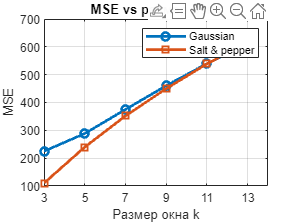


% График зависимости MSE от размера окна
figure('Color','w');
plot(ks, mseGauss, '-o', 'LineWidth', 2); hold on;
plot(ks, mseSP,    '-s', 'LineWidth', 2); hold off;
xlabel('Размер окна k'); ylabel('MSE');
title('MSE vs размер окна'); legend('Gaussian','Salt & pepper'); grid on;
xticks(ks);